# Smoothing Filters

## 1. Moving Average Filter

### Preliminaries

load("ECG_template.mat"); 
ECG = ECG_template; 

fs = 500; %Sampling Rate
time = (0:length(ECG)-1)/fs; %time_array

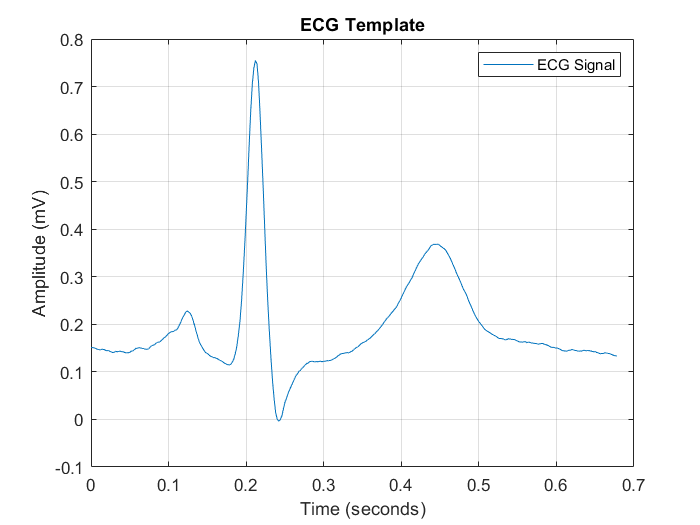

figure; %plot signal
plot(time, ECG);
title('ECG Template');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on; 
legend('ECG Signal'); 

We can see the P wave, the QRS complex and also the T wave here. 

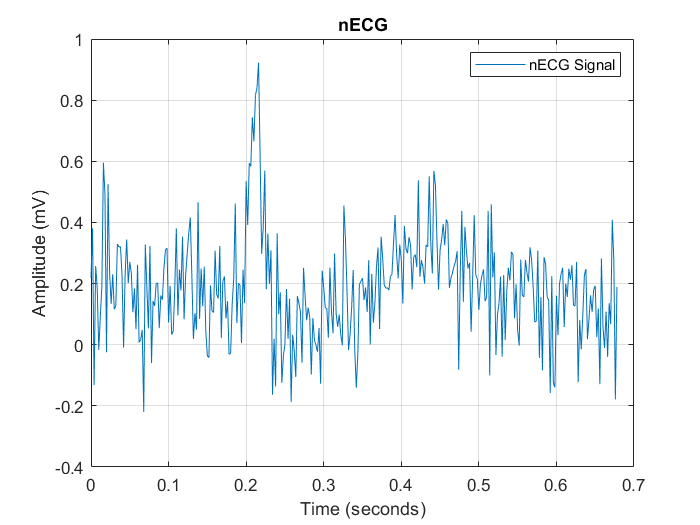

nECG = awgn(ECG,5,'measured'); % Adding Gaussian Noise to the signal

figure; %plot noisy signal
plot(time, nECG);
title('nECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on; 
legend('nECG Signal'); 

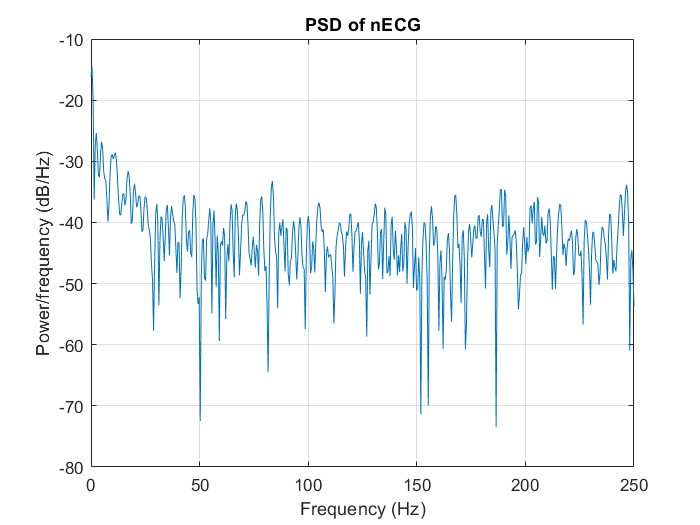

% Plotting  the frequency domain of the signals

nfft = 1024; % No. of frequency bins in the FFT
window = rectwin(length(nECG));

figure;
periodogram(nECG,window,nfft,fs);
title('PSD of nECG');

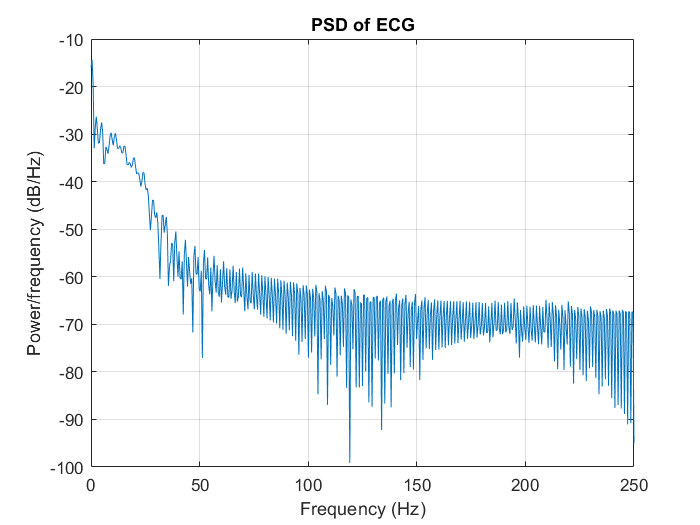


figure;
periodogram(ECG,window,nfft,fs);
title('PSD of ECG');

### MA3 Filter Implementation with a customized script

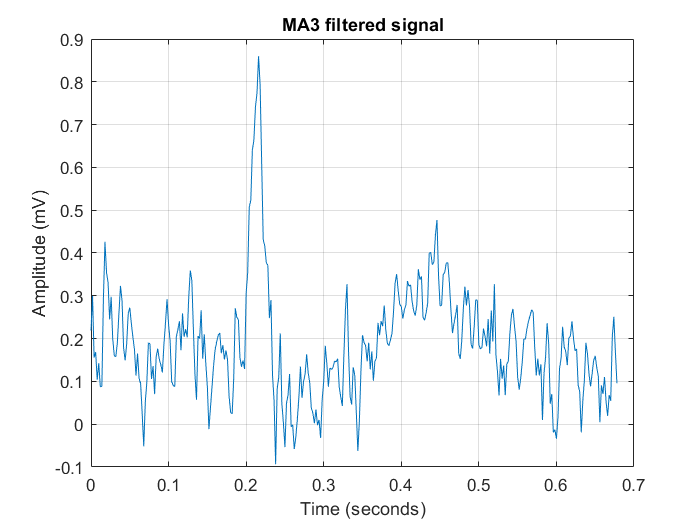

N = 3; %order is 3

ma3ECG_1 = ma3_filter(nECG,N);
figure;
plot(time, ma3ECG_1);
title('MA3 filtered signal');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on; 

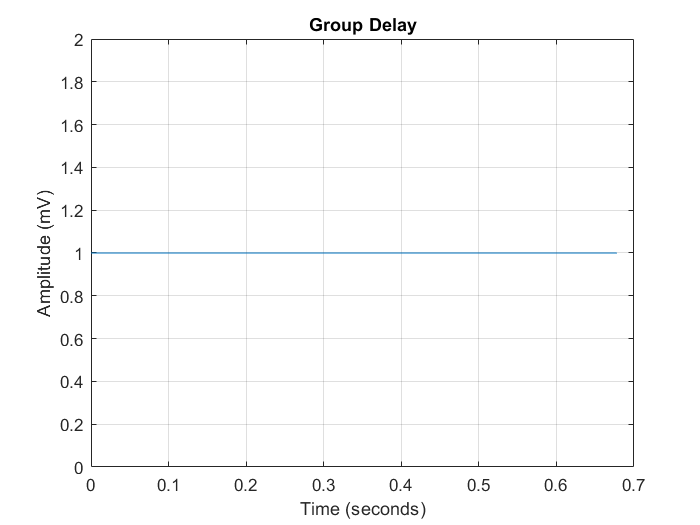

% Deriving the group delay

b = ones(1,N)/N;
[gd,w] = grpdelay(b,1,length(nECG));

figure;
plot(time, gd);
title('Group Delay');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on; 

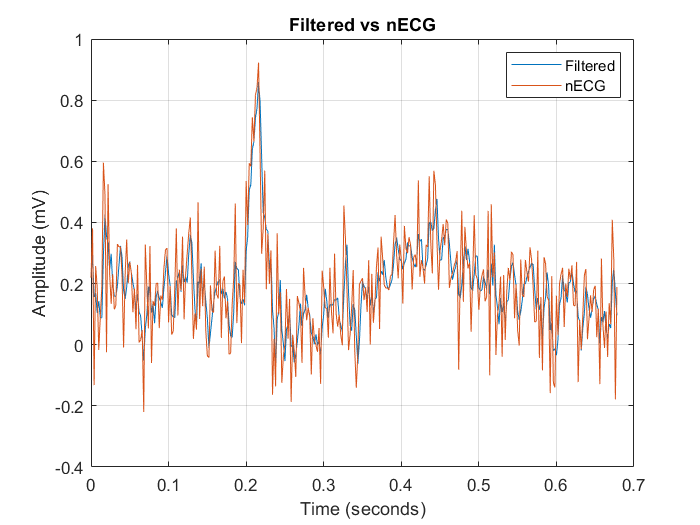

% Observing the delay

figure; 

plot(time, ma3ECG_1); 
hold on;  

plot(time, nECG);  

title('Filtered vs nECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('Filtered', 'nECG');  % Add legend to distinguish the plots

grid on;

Group delay is 1; meaning there is a delay of a single sample.

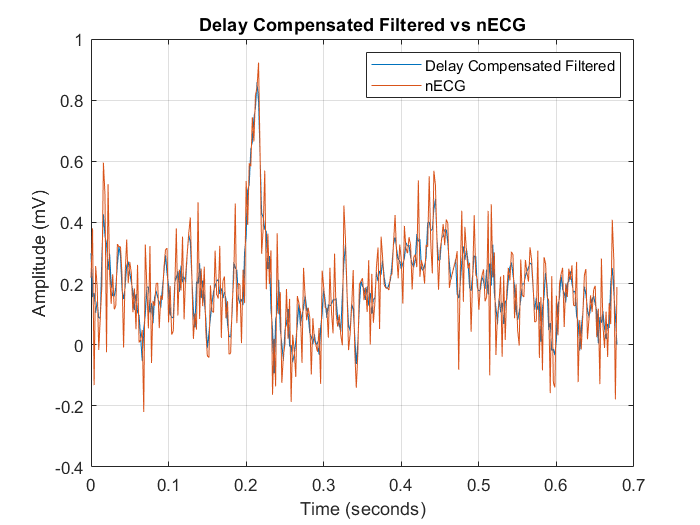

% Compensating the group delay through zero padding

figure; 

ma3ECG_1_delay_compensated = [ma3ECG_1(2:end),0];
plot(time, ma3ECG_1_delay_compensated); 
hold on;  

plot(time, nECG);  

title('Delay Compensated Filtered vs nECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('Delay Compensated Filtered', 'nECG');  % Add legend to distinguish the plots

grid on;

Compensated the delay, by adding a zero at the end and shifting the signal.

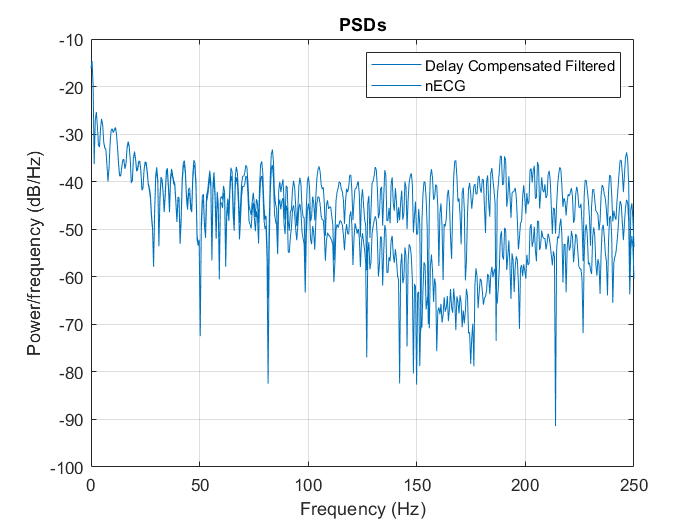

% Observing the PSD s. 

figure;
periodogram(ma3ECG_1_delay_compensated,window,nfft,fs);
title('PSD of nECG');

hold on;

periodogram(nECG,window,nfft,fs);
title('PSDs');

legend('Delay Compensated Filtered', 'nECG')

### MA(3) filter implementation with the MATLAB built-in function 

b = [1,1,1]/3; % Filter coefficients
a = 1;

ma3ECG_2 = filter(b,a,nECG);
ma3ECG_2_delay_compensated = [ma3ECG_2(2:end),0];

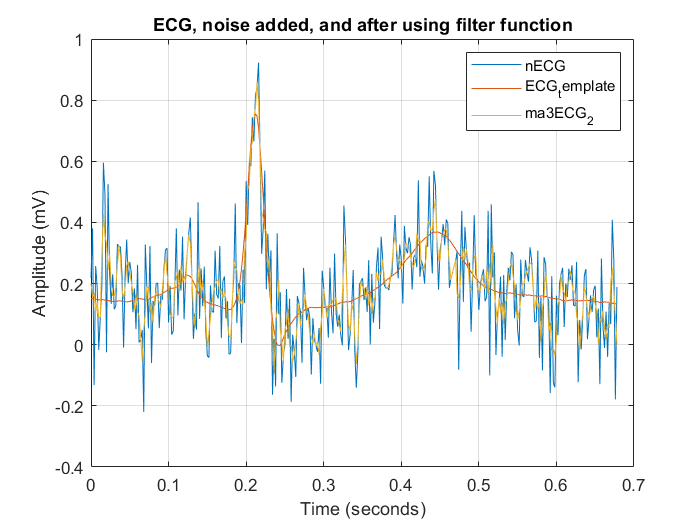

figure; % Comparing the effect of built in function

plot(time, nECG); 
hold on; 

plot(time, ECG_template); 
hold on;  

plot(time, ma3ECG_2_delay_compensated);  

title('ECG, noise added, and after using filter function');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('nECG','ECG_template','ma3ECG_2'); 

grid on;

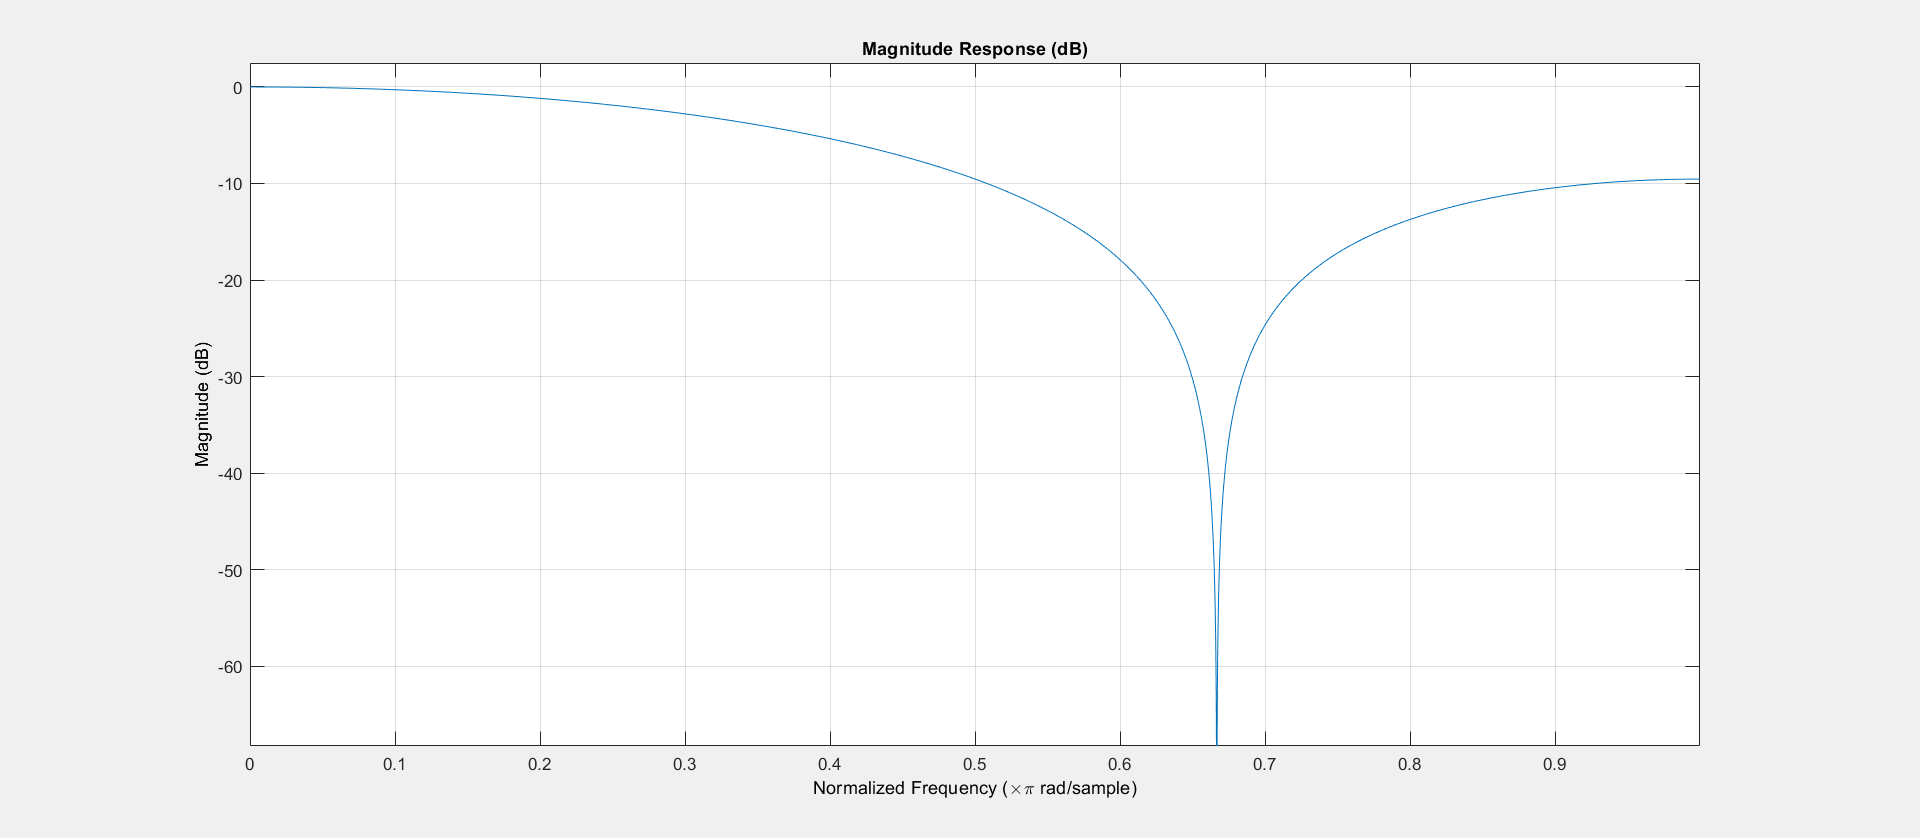

fvtool(b,a);

### MA(10) filter implementation with the MATLAB built-in function 

b = ones(1,10)/10; %Filter Coefficients
a = 1;

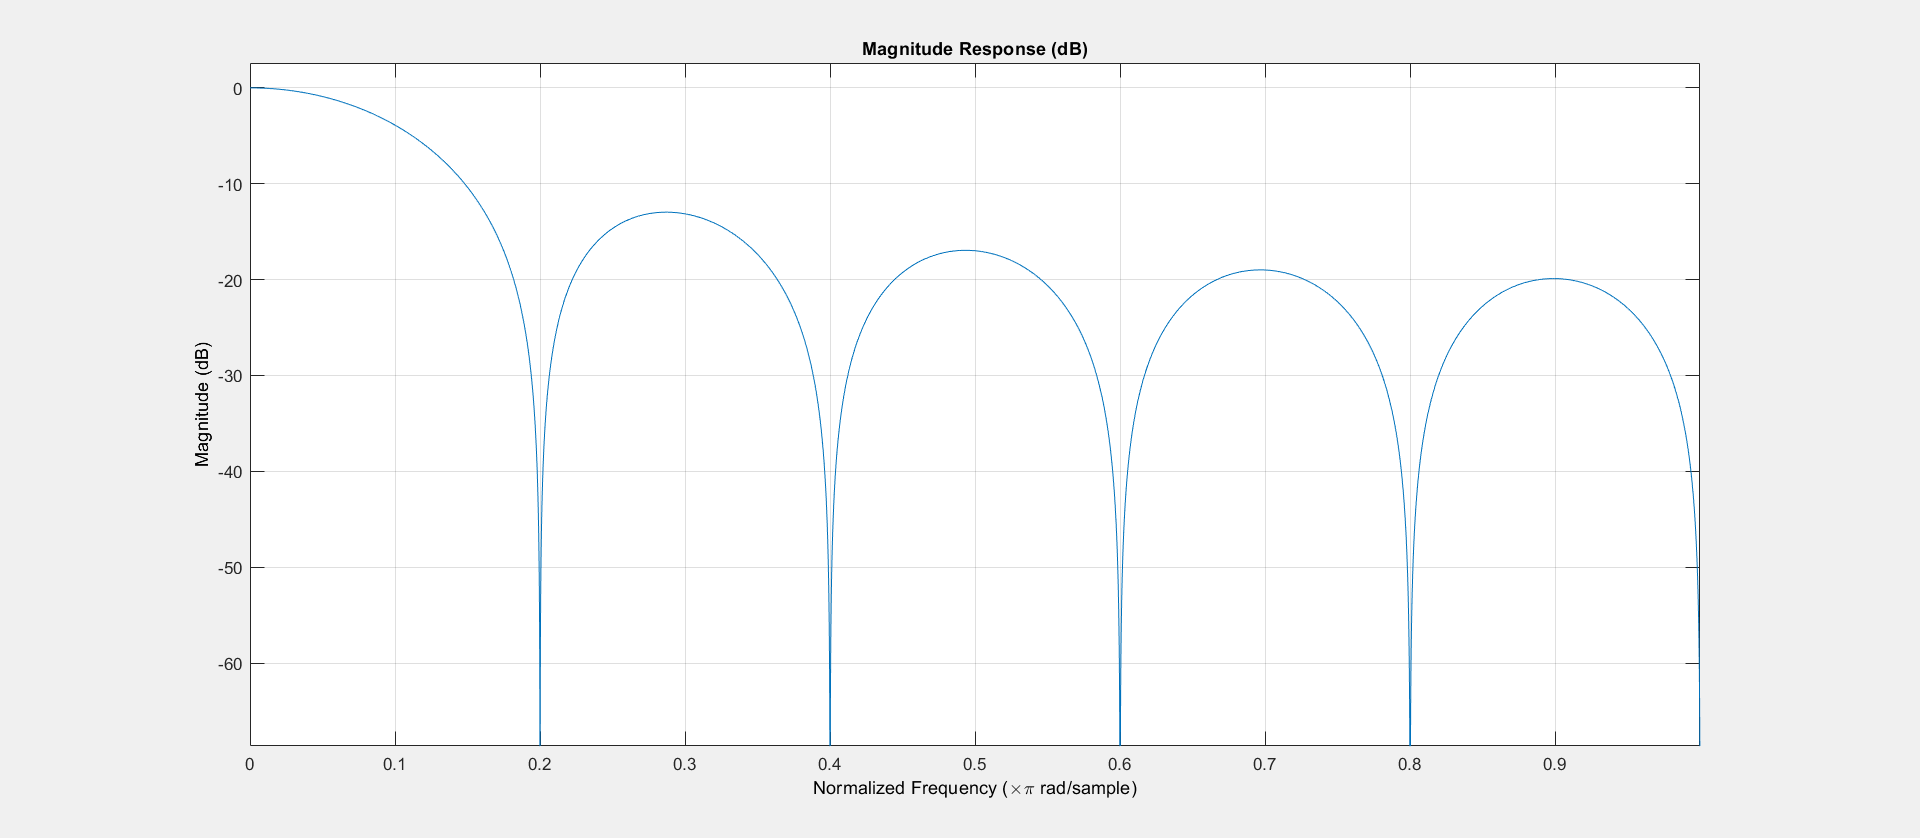

fvtool(b,a);

More higher frequencies are cut off. 

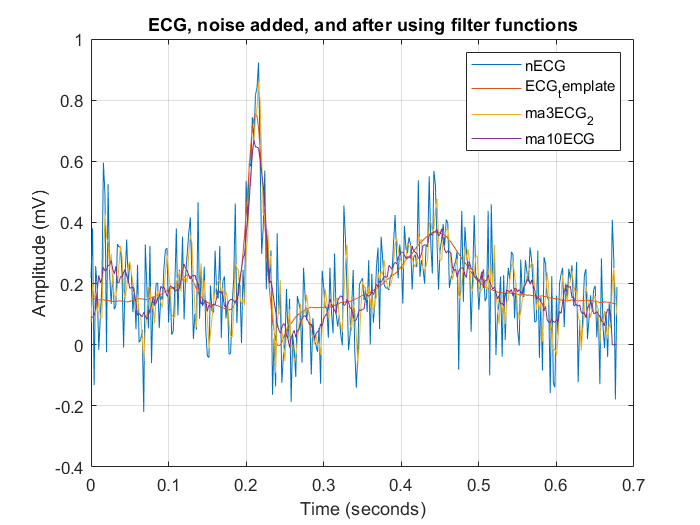

% Comparing impact with N=10

ma10ECG_with_delay = filter(b,a,nECG);
ma10ECG = [ma10ECG_with_delay(5:end),zeros(1,4)];

figure;

plot(time, nECG); 
hold on; 

plot(time, ECG_template); 
hold on;  

plot(time, ma3ECG_2);  
hold on;

plot(time, ma10ECG);

title('ECG, noise added, and after using filter functions');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('nECG','ECG_template','ma3ECG_2','ma10ECG');  % Add legend to distinguish the plots

grid on;

### Optimum MA(N) filter order 

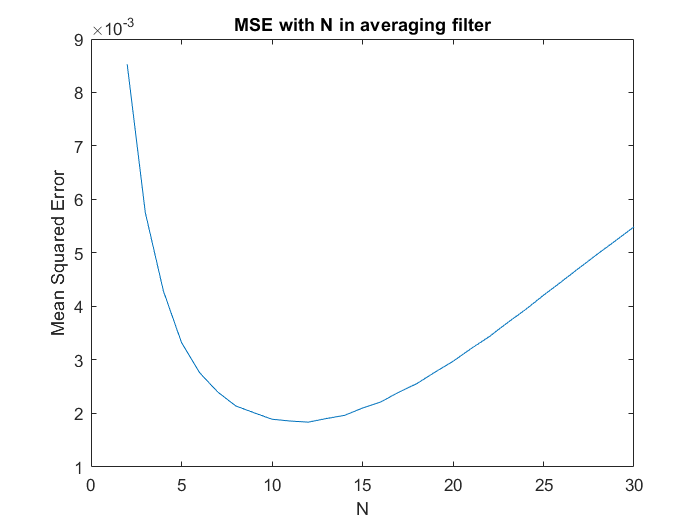

mse_values = [];
for j = 2:30
    
    % Compares N ranging from 2 to 30, the optimum is selected based
    % on the MSE.
    
    b = ones(1,j)/j;
    maN_ECG = filter(b,a,nECG);
    [gd_N,w_N] = grpdelay(b,a,length(nECG));
    gd_N_val = round(gd_N(1));
    mse_val = mse(maN_ECG((1+gd_N_val):end),ECG);
    mse_values = [mse_values, mse_val];
end

figure;

plot((2:30), mse_values);
title('MSE with N in averaging filter');
xlabel('N');
ylabel('Mean Squared Error');

Minimum is achieved at N = 13 

## 1.2 Savitzky-Golay Filter

### Application of SG(N,L) 

L = 11; 
N = 3; % order of the polynomial
L_ = 2*L+1; % No. of data points the polynomial is being fit to.

sg310ECG = sgolayfilt(nECG,N,L_); 

[b, g] = sgolay(N, L_);

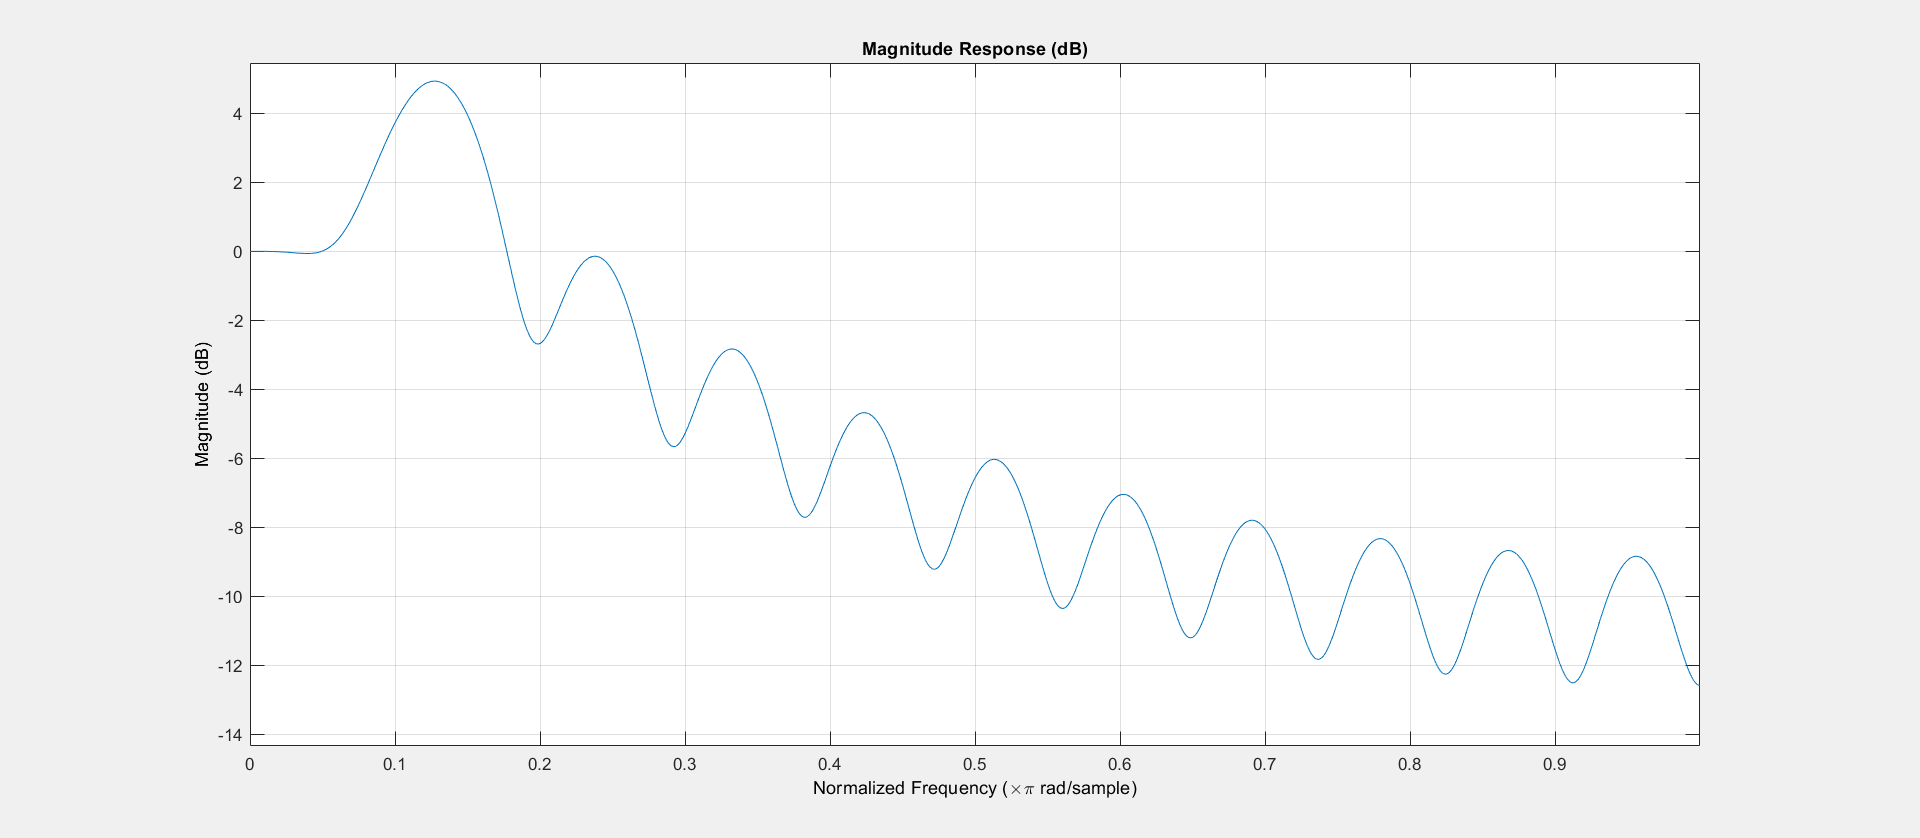

fvtool(b(1,:),1);

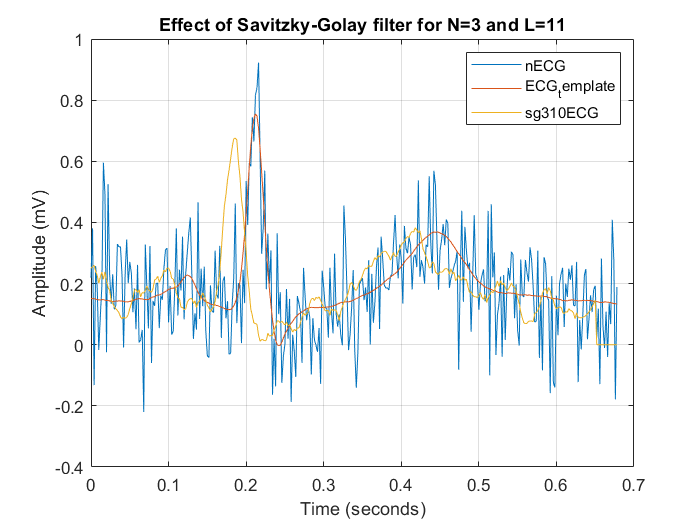

% Comparing with the original and noisy signals 

figure;

plot(time, nECG); 
hold on; 

plot(time, ECG_template); 
hold on;  

plot(time, sg310ECG);  

title('Effect of Savitzky-Golay filter for N=3 and L=11');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('nECG','ECG_template','sg310ECG');  % Add legend to distinguish the plots

grid on;

### Optimum SG(N,L) filter parameters 

max_L = round(length(ECG)/2-1); % to adhere to the condition
% that N<= L'-1 with L' = 2L+1 maximum L' is the length of the signal

% Both N and L will be varied to see the optimum of both

mse_sgolay_N_L = nan(max_L,2*max_L+1);

for L_i = 1: max_L 
    L_i_ = 2*L_i+1;
    for N_j = 1: (L_i_) % For each L, that N<= L'-1 with L' = 2L+1 should satisfy.
        sg_N_L_ECG = sgolayfilt(nECG,N_j-1,L_i_);
        mse_sgolay_N_L(L_i,N_j) = mse(sg_N_L_ECG, ECG);
        
    end
end

L_i_ = 3

L_i_ = 5

L_i_ = 7

L_i_ = 9

L_i_ = 11

L_i_ = 13

L_i_ = 15

L_i_ = 17

L_i_ = 19

L_i_ = 21

L_i_ = 23

L_i_ = 25

L_i_ = 27

L_i_ = 29

L_i_ = 31

L_i_ = 33

L_i_ = 35

L_i_ = 37

L_i_ = 39

L_i_ = 41

L_i_ = 43

L_i_ = 45

L_i_ = 47

L_i_ = 49

L_i_ = 51

L_i_ = 53

L_i_ = 55

L_i_ = 57

L_i_ = 59

L_i_ = 61

L_i_ = 63

L_i_ = 65

L_i_ = 67

L_i_ = 69

L_i_ = 71

L_i_ = 73

L_i_ = 75

L_i_ = 77

L_i_ = 79

L_i_ = 81

L_i_ = 83

L_i_ = 85

L_i_ = 87

L_i_ = 89

L_i_ = 91

L_i_ = 93

L_i_ = 95

L_i_ = 97

L_i_ = 99

L_i_ = 101

L_i_ = 103

L_i_ = 105

L_i_ = 107

L_i_ = 109

L_i_ = 111

L_i_ = 113

L_i_ = 115

L_i_ = 117

L_i_ = 119

L_i_ = 121

L_i_ = 123

L_i_ = 125

L_i_ = 127

L_i_ = 129

L_i_ = 131

L_i_ = 133

L_i_ = 135

L_i_ = 137

L_i_ = 139

L_i_ = 141

L_i_ = 143

L_i_ = 145

L_i_ = 147

L_i_ = 149

L_i_ = 151

L_i_ = 153

L_i_ = 155

L_i_ = 157

L_i_ = 159

L_i_ = 161

L_i_ = 163

L_i_ = 165

L_i_ = 167

L_i_ = 169

L_i_ = 171

L_i_ = 173

L_i_ = 175

L_i_ = 177

L_i_ = 179

L_i_ = 181

L_i_ = 183

L_i_ = 185

L_i_ = 187

L_i_ = 189

L_i_ = 191

L_i_ = 193

L_i_ = 195

L_i_ = 197

L_i_ = 199

L_i_ = 201

L_i_ = 203

L_i_ = 205

L_i_ = 207

L_i_ = 209

L_i_ = 211

L_i_ = 213

L_i_ = 215

L_i_ = 217

L_i_ = 219

L_i_ = 221

L_i_ = 223

L_i_ = 225

L_i_ = 227

L_i_ = 229

L_i_ = 231

L_i_ = 233

L_i_ = 235

L_i_ = 237

L_i_ = 239

L_i_ = 241

L_i_ = 243

L_i_ = 245

L_i_ = 247

L_i_ = 249

L_i_ = 251

L_i_ = 253

L_i_ = 255

L_i_ = 257

L_i_ = 259

L_i_ = 261

L_i_ = 263

L_i_ = 265

L_i_ = 267

L_i_ = 269

L_i_ = 271

L_i_ = 273

L_i_ = 275

L_i_ = 277

L_i_ = 279

L_i_ = 281

L_i_ = 283

L_i_ = 285

L_i_ = 287

L_i_ = 289

L_i_ = 291

L_i_ = 293

L_i_ = 295

L_i_ = 297

L_i_ = 299

L_i_ = 301

L_i_ = 303

L_i_ = 305

L_i_ = 307

L_i_ = 309

L_i_ = 311

L_i_ = 313

L_i_ = 315

L_i_ = 317

L_i_ = 319

L_i_ = 321

L_i_ = 323

L_i_ = 325

L_i_ = 327

L_i_ = 329

L_i_ = 331

L_i_ = 333

L_i_ = 335

L_i_ = 337

L_i_ = 339

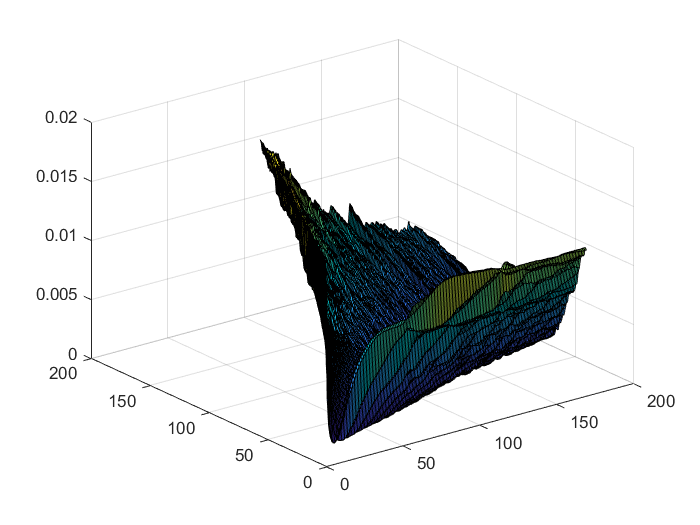

%Visualizing the mse values for N and L

[X, Y] = meshgrid(1:max_L, 0:2*max_L); % N can range from zero to L'-1

figure;
surf(X, Y, mse_sgolay_N_L');

[min_val, indices] = min(mse_sgolay_N_L(:)); %indices are set such that they represent the N and L values
[row, col] = ind2sub(size(mse_sgolay_N_L), indices);

L = 17

N = 4

% Comparision with the optimal scenario

L = 17;
N = 4;
L_ = 2*L+1;
tic
sg_17_4_ECG = sgolayfilt(nECG,N,L_);
toc

Elapsed time is 0.005932 seconds.


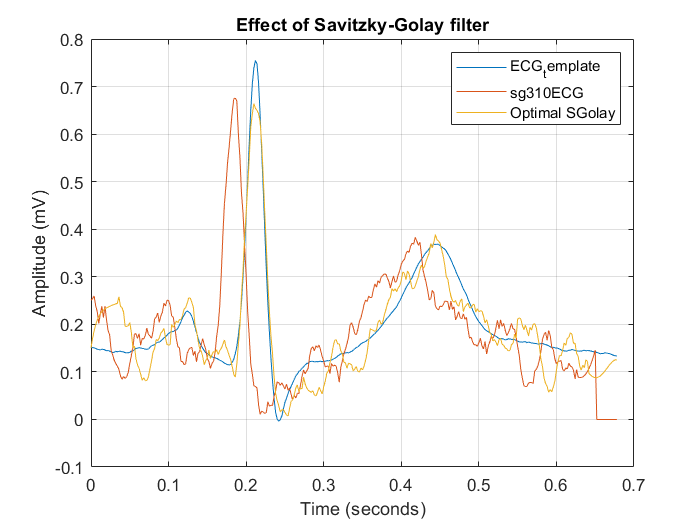


figure;

plot(time, ECG_template); 
hold on;  

plot(time, sg310ECG); 
hold on; 

plot(time, sg_17_4_ECG);  

title('Effect of Savitzky-Golay filter');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('ECG_template','sg310ECG','Optimal SGolay');  % Add legend to distinguish the plots

grid on;

`Elapsed time is 0.005500 seconds.`

% Time taken for optimal moving average. at N= 13.

tic
b = ones(1,13)/13;
maN_ECG_with_delay = filter(b,a,nECG);
maN_ECG = [maN_ECG_with_delay(7:end),zeros(1,6)]

maN_ECG =     0.0759    0.0906    0.1364    0.1743    0.1724    0.2128    0.2308    0.2243    0.2127    0.2318    0.2218    0.2327    0.2586    0.2762    0.2790    0.2325    0.2123    0.2406    0.2157    0.2186    0.2263    0.2168    0.2220    0.2161    0.2109    0.1868    0.1634    0.1497    0.1335    0.1410    0.1290    0.1176    0.1216    0.0990    0.1018    0.0975    0.1090    0.1044    0.1080    0.1192    0.1268    0.1629    0.1616    0.1714    0.1729    0.1629    0.1700    0.1625    0.1670    0.1809


toc

Elapsed time is 0.037213 seconds.


`Elapsed time is 0.004374 seconds.`

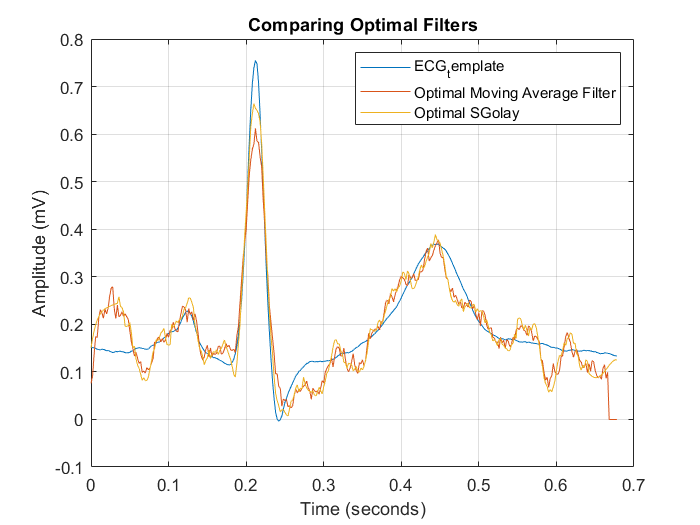

% Comparing features of optimal filtered signals
figure;

plot(time, ECG_template); 
hold on;  

plot(time, maN_ECG); 
hold on; 

plot(time, sg_17_4_ECG);  

title('Comparing Optimal Filters');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('ECG_template','Optimal Moving Average Filter','Optimal SGolay');  % Add legend to distinguish the plots

grid on;